clear
clc
close all

ModularAplysia_1282022_withSNS_initialization;
load("params_1282022.mat")
endTime = 200;

## Swallowing

MechanicsParaOriginal;
CtrlParaSNSTuning;
mu_s_g = 0.45;
mu_k_g = 0.3;
mu_s_h = 0.3;
mu_k_h = 0.3;
max_I3ant = 1.2;

sens_chemical_lips = 1;
sens_mechanical_lips = 1;
sens_mechanical_grasper = 1;
fixation_type = 1;

simout_swallowing_load = [];
num = 4;

for k = 1:num
    seaweed_strength = 0.0 + 0.15 * (k - 1);
    simout_swallowing_load = [simout_swallowing_load, sim('ModularAplysia_1282022_withSNS_originalMechanics.slx', 'StopTime',string(endTime),'MinStep','0.001')];
end

## Plot Parameters

figure_width = 320;
figure_height = figure_width * 2 /(sqrt(5) - 1) * 0.9 * 1; %%%%%%%%%%%%% *0.9
width = 0.775;
delta_width_axis = 0.03;
delta_height_axis = delta_width_axis * figure_width / figure_height;
height_xgh = 0.1 / 0.9 * 1;  %%%%%%%%%%%%% * 1
height_force = 0.025 / 0.9 * 1;  %%%%%%%%%%%%% * 1
delta_height_xgh = 0.05 / 0.9;
delta_height_force = 0.025 / 0.9;
top = 0.93;   %%%%%%%%%%%%% 0.93
strength_height = 0.75 / 0.9;

## **Plot Figures**

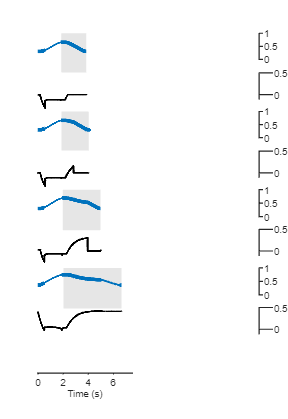

f = figure;
f.Position = [100, 100, figure_width, figure_height];
set(gcf,'Color','white')
% set(gcf, 'color', 'none'); 
timespan = 30;
timebeginuntil = 100;
tickwidth = 1;
ax = [];
for k = 1:num
    [protractionRectangles_biting_fb,~] = prorec(simout_swallowing_load(k),timespan,timebeginuntil);
    % [protractionRectangles_biting_wofb,~] = prorec(simout_swallowing_load_wofb(k),timespan,timebeginuntil);
    index = protractionRectangles_biting_fb(1,1):protractionRectangles_biting_fb(2,1);
    % index_wofb = protractionRectangles_biting_wofb(1,1):protractionRectangles_biting_wofb(2,1);
    subplot(2 * num + 1,2,4 * k - 3)
    shade_left = simout_swallowing_load(k).tout(protractionRectangles_biting_fb(1,2)) - simout_swallowing_load(k).tout(protractionRectangles_biting_fb(1,1));
    shade_bottom = -(delta_height_force + height_force) / height_xgh;
    shade_width =  simout_swallowing_load(k).tout(protractionRectangles_biting_fb(2,1)) - simout_swallowing_load(k).tout(protractionRectangles_biting_fb(1,2));
    shade_height = (delta_height_force + height_force + height_xgh) / height_xgh;
    
    grasper_motion = simout_swallowing_load(k).x_g.Data(index) - simout_swallowing_load(k).x_h.Data(index);
    grasper_pressure = simout_swallowing_load(k).grasper_friction_state.Data(index);
    idy = grasper_pressure < 0.5;
    grasper_motion_pressure = grasper_motion;
    grasper_motion_pressure(idy) = NaN;

    % grasper_motion_wofb = simout_swallowing_load_wofb(k).x_g.Data(index) - simout_swallowing_load_wofb(k).x_h.Data(index);
    % grasper_pressure_wofb = simout_swallowing_load_wofb(k).grasper_friction_state.Data(index_wofb);
    % idy_wofb = grasper_pressure_wofb < 0.5;
    % grasper_motion_pressure_wofb = grasper_motion_wofb;
    % grasper_motion_pressure_wofb(idy_wofb) = NaN;

    
    rectangle('Position',[shade_left, shade_bottom, shade_width, shade_height],'FaceColor',[.9 .9 .9],'EdgeColor','none')
    hold on
    t = simout_swallowing_load(k).tout(index) - simout_swallowing_load(k).tout(index(1));
    % simout_swallowing_load_wofb(k).tout(index_wofb(end)) - simout_swallowing_load_wofb(k).tout(index_wofb(1))
    plot(t,grasper_motion_pressure,'Color',[0 0.4470 0.7410],'LineWidth',3.5)
    plot(t,grasper_motion,'Color',[0 0.4470 0.7410],'LineWidth',1.75)
    hold off
    xlim = [0,7.5];
    ylim = [0,1];
    xticks = [];
    yticks = [];
    xticklabels = string(xticks);
    yticklabels = string(yticks);
    set(gca,'Box','off','YAxisLocation','right',...
        'XLim',xlim,'YLim',ylim,...
        'XTick',xticks,'XTickLabel',xticklabels,...
        'YTick',yticks,'YTickLabel',yticklabels,...
        'TickDir','out','LineWidth',tickwidth,...
        'YGrid','off','Clipping','Off','color','none')
    ax{4 * k - 3} = gca;
    set(ax{4 * k - 3},'xcolor','none');
    ax{4 * k - 3}.XAxis.Label.Color = [0 0 0];
    ax{4 * k - 3}.XAxis.Label.Visible = 'on';
    set(ax{4 * k - 3},'ycolor','none');
    ax{4 * k - 3}.YAxis.Label.Color = [0 0 0];
    ax{4 * k - 3}.YAxis.Label.Visible = 'on';

    subplot(2 * num + 1,2,4 * k - 1)
    plot(simout_swallowing_load(k).tout(index) - simout_swallowing_load(k).tout(index(1)),simout_swallowing_load(k).force(index),'LineWidth',1.75,'Color','k')
    xlim = [0,7.5];
    ylim = [-0.1,0.5];

    xticks = [];
    yticks = [];
    xticklabels = string(xticks);
    yticklabels = string(yticks);
    set(gca,'Box','off','YAxisLocation','right',...
        'XLim',xlim,'YLim',ylim,...
        'XTick',xticks,'XTickLabel',xticklabels,...
        'YTick',yticks,'YTickLabel',yticklabels,...
        'TickDir','out','LineWidth',tickwidth,...
        'YGrid','off','Clipping','Off','color','none')
    ax{4 * k - 1} = gca;
    set(ax{4 * k - 1},'xcolor','none');
    ax{4 * k - 1}.XAxis.Label.Color = [0 0 0];
    ax{4 * k - 1}.XAxis.Label.Visible = 'on';
    set(ax{4 * k - 1},'ycolor','none');
    ax{4 * k - 1}.YAxis.Label.Color = [0 0 0];
    ax{4 * k - 1}.YAxis.Label.Visible = 'on';
end

for k = 1:num
    subplot(2 * num + 1,2,4 * k - 2)
    xlim = [0,7.5];
    ylim = [0,1];
    xticks = [];
    yticks = 0:0.5:1;
    xticklabels = string(xticks);
    yticklabels = string(yticks);
    set(gca,'Box','off','YAxisLocation','right',...
        'XLim',xlim,'YLim',ylim,...
        'XTick',xticks,'XTickLabel',xticklabels,...
        'YTick',yticks,'YTickLabel',yticklabels,...
        'TickDir','out','LineWidth',tickwidth,'TickLength',[0.0352,0.01],...
        'YGrid','off','Clipping','Off','color','none','FontSize',8)
    ax{4 * k - 2} = gca;
    set(ax{4 * k - 2},'xcolor','none');
    ax{4 * k - 2}.XAxis.Label.Color = [0 0 0];
    ax{4 * k - 2}.XAxis.Label.Visible = 'on';

    subplot(2 * num + 1,2,4 * k)
    xlim = [0,7.5];
    ylim = [-0.1,0.5];

    xticks = [];
    yticks = [0, 0.5];
    xticklabels = string(xticks);
    yticklabels = string(yticks);
    set(gca,'Box','off','YAxisLocation','right',...
        'XLim',xlim,'YLim',ylim,...
        'XTick',xticks,'XTickLabel',xticklabels,...
        'YTick',yticks,'YTickLabel',yticklabels,...
        'TickDir','out','LineWidth',tickwidth,'TickLength',[0.1406,0.01],...
        'YGrid','off','Clipping','Off','color','none','FontSize',8)
    ax{4 * k} = gca;
    set(ax{4 * k},'xcolor','none');
    ax{4 * k}.XAxis.Label.Color = [0 0 0];
    ax{4 * k}.XAxis.Label.Visible = 'on';
end

subplot(2 * num + 1,2,4 * num + 1)
xlim = [0,7.5];
ylim = [0,1];

xticks = 0:2:8;
yticks = [];
xticklabels = string(xticks);
yticklabels = string(yticks);
set(gca,'Box','off','YAxisLocation','right',...
    'XLim',xlim,'YLim',ylim,...
    'XTick',xticks,'XTickLabel',xticklabels,...
    'YTick',yticks,'YTickLabel',yticklabels,...
    'TickDir','out','LineWidth',tickwidth,'TickLength',[0.0073,0.01],...
    'YGrid','off','Clipping','Off','color','none','FontSize',8)
xlabel('Time (s)','FontSize',8)
ax{4 * num + 1} = gca;
set(ax{4 * num + 1},'ycolor','none');
ax{4 * num + 1}.YAxis.Label.Color = [0 0 0];
ax{4 * num + 1}.YAxis.Label.Visible = 'on';

subplot(2 * num + 1,2,4 * num + 2)
plot([0,8],[1000,1000],'LineWidth',1.75);
hold on
plot([0,8],[1000,1000],'LineWidth',1.75,'Color','k');
xlim = [0,7.5];
ylim = [0,1];
set(gca,'Box','off','XLim',xlim,'YLim',ylim,'Clipping','Off','color','none')
ax{4 * num + 2} = gca;
set(ax{4 * num + 2},'xcolor','none');
ax{4 * num + 2}.XAxis.Label.Color = [0 0 0];
ax{4 * num + 2}.XAxis.Label.Visible = 'on';
set(ax{4 * num + 2},'ycolor','none');
ax{4 * num + 2}.YAxis.Label.Color = [0 0 0];

ax{4 * num + 2}.YAxis.Label.Visible = 'on';

## **Orangize Subplots**

ax{1}.Position(2) = top - height_xgh;
ax{1}.Position(4) = height_xgh;
ax{2}.Position(2) = top - height_xgh;
ax{2}.Position(4) = height_xgh;

cols = 1;
for rows = 1:2 * num + 1
    index = 2 * rows + cols - 2;
    ax{index}.Position(1) = 0.12;
    ax{index}.Position(3) = width;
end

cols = 2;
for rows = 1:2 * num + 1
    index = 2 * rows + cols - 2;
    ax{index}.Position(1) = ax{index - 1}.Position(1) + ax{index - 1}.Position(3) + delta_width_axis / 2;
    ax{index}.Position(3) = delta_width_axis / 2;
end

for rows = 2:2 * num
    if mod(rows, 2) ~= 0
        for cols = 1:2
            index = 2 * rows + cols - 2;
            ax{index}.Position(2) = ax{index - 2}.Position(2) - height_xgh - delta_height_xgh;
            ax{index}.Position(4) = height_xgh;
        end
    else
        for cols = 1:2
            index = 2 * rows + cols - 2;
            ax{index}.Position(2) = ax{index - 2}.Position(2) - height_force - delta_height_force;
            ax{index}.Position(4) = height_force;
        end
    end

end

rows = 2 * num + 1

rows = 9

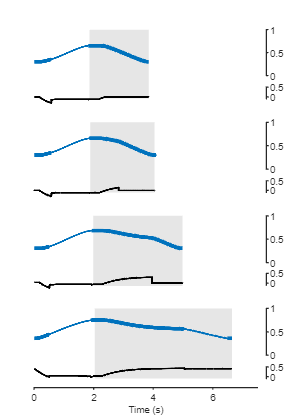

for cols = 1:2
    index = 2 * rows + cols - 2;
    ax{index}.Position(2) = ax{index - 1}.Position(2) - delta_height_axis;
    ax{index}.Position(4) = delta_height_axis / 2;
end

## **Legend**

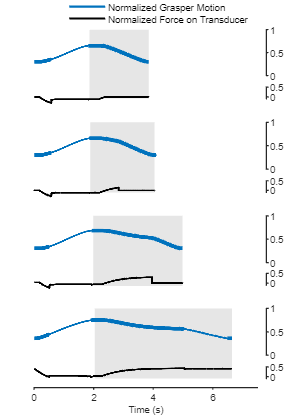

set(f, 'CurrentAxes', ax{end})
legend('Normalized Grasper Motion','Normalized Force on Transducer','Box','off','Position', [0.4,0.95,0.3,0.04],'FontSize',8) %%%%%%%%%%% 0.95

## **X Grid**

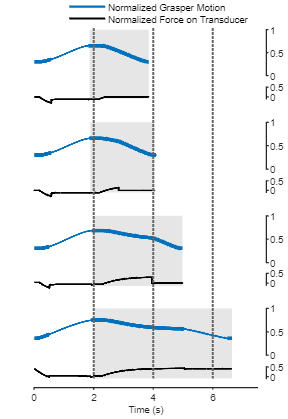

set(f, 'CurrentAxes', ax{end - 3})
y = [-0.1, -0.1 + (top - ax{end - 3}.Position(2)) / height_force * 0.6]; %%%%%%%%%%%%%%%%% *0.6
for x = 2:2:6
    line(x * ones(size(y)), y,'LineStyle',':','LineWidth',1.75,'Color',[0.4,0.4,0.4])
end

## **Seaweed Strength**

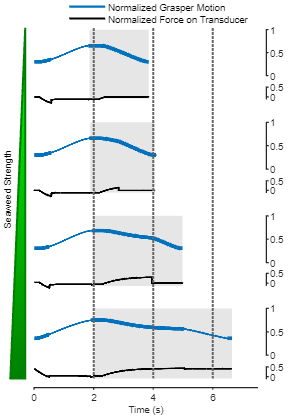

% for k = 1:num
%     set(f, 'CurrentAxes', ax{4 * k - 3})
%     strength_left = -8 * delta_width_axis / width - max((k - 1) * 0.15, 0.01); 
%     strength_bottom = 1 - (height_xgh + delta_height_force + height_force) / height_xgh / 2 - strength_height / 2;
%     strength_width = max((k - 1) * 0.15, 0.01);
%     rectangle('Position',[strength_left, strength_bottom, strength_width, strength_height],'FaceColor',[226 240 217] / 255,'EdgeColor','none')
%     text(strength_left - 0.05,strength_bottom + strength_height / 2,string((k - 1) * 0.15),'HorizontalAlignment','right','VerticalAlignment','middle','FontSize',10)
% end
% set(f, 'CurrentAxes', ax{1})
% str = {'Seaweed','Strength'};
% text(-0.6,1.2,str,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',10)


set(f, 'CurrentAxes', ax{end - 3})
x = [-0.8,-0.3,-0.3,-0.8];
y = [-0.1,-0.1,-0.1 + (top - ax{end - 3}.Position(2)) / height_force * 0.6,-0.1]; %%%%%%%%%%%%%%%%% *0.6
patch(x,y,(y - min(y))/(max(y) - min(y)),'EdgeColor',[0,0.5,0],'LineWidth',1.75)

cmap = zeros(256,3);
cmap(:,2)=linspace(0.5,1,256);
colormap(cmap);
h=text(-0.9,(-0.1 + (top - ax{end - 3}.Position(2)) / height_force * 0.3) * 0.85,"Seaweed Strength",'FontSize',8,'VerticalAlignment','middle','HorizontalAlignment','left');
set(h,'Rotation',90);

## Local Functions

function [protractionRectangles,index] = prorec(simout,timespan,timebeginuntil)
    startnum = 0;
    endnum = length(simout.tout);
    simout.xgh = simout.x_g.Data' - simout.x_h.Data';
    grasper_rel_pos = simout.xgh;
    numProtractionBoxes = 0;
    numRetractionBoxes = 0;
    protraction = 1;
    protractionRectangles=[0,0];
    retractionRectangles=[0,0];
    for ind=startnum+2:endnum
        if (grasper_rel_pos(ind) - grasper_rel_pos(ind-1))/(simout.tout(ind) - simout.tout(ind-1)) > -1e-2 * 0
            %protraction
            if(protraction == 0)
                numProtractionBoxes=numProtractionBoxes+1;
                protraction = 1;
                %end the last retractionrectangle
                if(numRetractionBoxes>0)
                    retractionRectangles(numRetractionBoxes,2) = ind;
                end
                %start a new protractionrectangle
                protractionRectangles(numProtractionBoxes,1) = ind;
            end
        else
            %retraction
            if(protraction == 1)
                numRetractionBoxes=numRetractionBoxes+1;
                protraction = 0;
                %end the last retractionrectangle
                retractionRectangles(numRetractionBoxes,1) = ind;
                %start a new protractionrectangle
                if(numProtractionBoxes>0)
                    protractionRectangles(numProtractionBoxes,2) = ind;
                end
            end
        end
    end
    
    if protractionRectangles(end,2) == 0
        protractionRectangles(end,2) = endnum;
    end
    
    k = 2;
    while 1
        if k > size(protractionRectangles,1)
            break;
        elseif simout.tout(protractionRectangles(k,1)) - simout.tout(protractionRectangles(k-1,2)) < 1.5
            protractionRectangles(k-1,2) = protractionRectangles(k,2);
            protractionRectangles(k,:) = [];
            continue;
        end
        k = k + 1;
    end

    k = 1;
    while 1
        if k > size(protractionRectangles,1)
            break;
        elseif simout.tout(protractionRectangles(k,2)) - simout.tout(protractionRectangles(k,1)) < 1
            protractionRectangles(k,:) = [];
            continue;
        end
        k = k + 1;
    end   

    protractionRectangles = protractionRectangles(simout.tout(protractionRectangles(:,1)) > timebeginuntil,:);
    
    beginindex = protractionRectangles(1,1);
    endindex = find(simout.tout >= simout.tout(beginindex) + timespan,1,'first');
    index = beginindex:endindex;
end